edfData1 = edfread("chb01_03.edf");

edfData2 = edfread("chb01_04.edf");

edfData3 = edfread("chb01_15.edf");

edfData4 = edfread("chb01_16.edf");

edfData5 = edfread("chb01_18.edf");

edfData6 = edfread("chb01_26.edf");

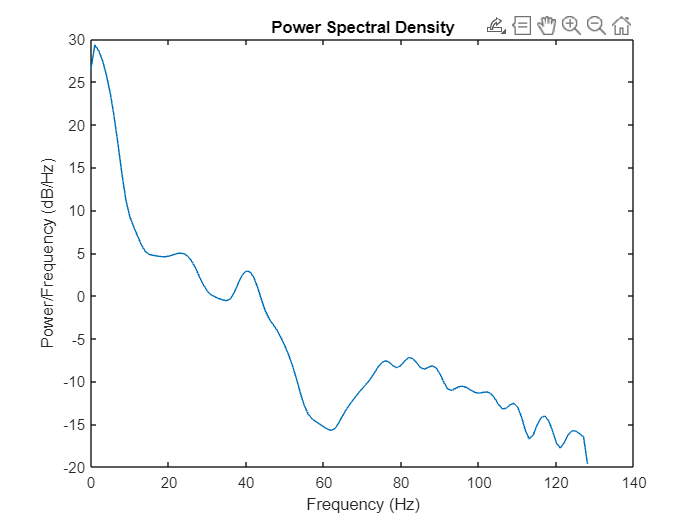

edfData11 = table2array(edfData1);
edfData22 = table2array(edfData2);
edfData33 = table2array(edfData3);
edfData44 = table2array(edfData4);
edfData55 = table2array(edfData5);
edfData66 = table2array(edfData6);
% Calculate PSD using pwelch
[pxx, f] = pwelch(edfData66, [], [], [], 256); % Assuming a sampling frequency of 256
% Plot the PSD
figure;
plot(f, 10*log10(pxx));
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)'); 
title('Power Spectral Density');